# 基础倒立摆小车推导

# 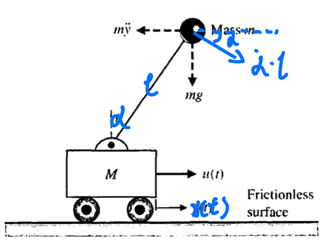

# 构建动力学方程

clear
close all
syms M m g l 
syms x(t) alpha(t)
syms u(t)
K = 0.5*M*(diff(x(t),t))^2+0.5*m*(diff(x,t)+diff(alpha,t)*l*cos(alpha))^2 + 0.5*m*(diff(alpha,t)*l*sin(alpha))^2

$$K(t) = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}$$

P = m*g*l*cos(alpha)

$$P(t) = g\,l\,m\,\cos\left(\alpha \left(t\right)\right)$$

定义拉格朗日算子L

L = K - P;
Dyn_Eqn(t)= [diff(diff(L,diff(x(t),t)),t) - diff(L,x) == u;
           diff(diff(L,diff(alpha(t),t)),t) - diff(L,alpha) == 0]

$$Dyn\_Eqn(t) = \begin{array}{l} \left(\begin{array}{c} \frac{m\,\left(-2\,l\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}+2\,l\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{3}+2\,\sigma_{2}\right)}{2}+M\,\sigma_{2}=u\left(t\right)\\ l\,m\,\cos\left(\alpha \left(t\right)\right)\,\left(l\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{3}-l\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}+\sigma_{2}\right)+l^{2}\,m\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{3}-g\,l\,m\,\sin\left(\alpha \left(t\right)\right)+l^{2}\,m\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

# 线性化

在$x$$\dot x$$\alpha \dot \alpha$这四个状态变量都趋近于0时，系统处于可线性化的状态

特别地，$sin(\alpha) \to \alpha$

Dyn_Eqn_lnr = [(m*(2*l*diff(alpha(t), t, t) + 2*diff(x(t), t, t)))/2 + M*diff(x(t), t, t) == u(t);
               m*(l^2)*diff(alpha,t,t) + m*l*diff(x,t,t) - m*g*l*alpha == 0]

$$Dyn\_Eqn\_lnr(t) = \left(\begin{array}{c} \frac{m\,\left(2\,l\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)}{2}+M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=u\left(t\right)\\ m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+m\,l\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-g\,m\,\alpha \left(t\right)\,l=0 \end{array}\right)$$

syms x_ddot alpha_ddot
% 简化为一元二次方程，进一步求解 x_ddot 和 alpha_ddot
Dyn_Eqn_lnr_sym = [(m*(2*l*alpha_ddot+ 2*x_ddot))/2 + M*x_ddot == u(t);
                    m*(l^2)*alpha_ddot + m*l*x_ddot - m*g*l*alpha == 0]

$$Dyn\_Eqn\_lnr\_sym(t) = \left(\begin{array}{c} M\,\ddot{x}+\frac{m\,\left(2\,\ddot{x}+2\,\ddot{\alpha }\,l\right)}{2}=u\left(t\right)\\ l\,m\,\ddot{x}+\ddot{\alpha }\,l^{2}\,m-g\,l\,m\,\alpha \left(t\right)=0 \end{array}\right)$$

Dyn_lnr_ans = solve(Dyn_Eqn_lnr_sym, [x_ddot, alpha_ddot])

Dyn_lnr_ans = 包含以下字段的 struct :
        x_ddot: (u(t) - g*m*alpha(t))/M
    alpha_ddot: (g*m*alpha(t) - u(t) + M*g*alpha(t))/(M*l)


# 欢迎来到状态空间

A = sym(zeros(4,4));
B = sym(zeros(4,1));
A(1,2) = 1;
A(3,4) = 1;
A(2,3) = diff(Dyn_lnr_ans.x_ddot, alpha);
A(4,3) = diff(Dyn_lnr_ans.alpha_ddot, alpha);
B(2,1) = diff(Dyn_lnr_ans.x_ddot, u);
B(4,1) = diff(Dyn_lnr_ans.alpha_ddot, u);

% 由于之后不需要�Matlab进行求导等复杂运算，所以重新定义了符号��，取代了对符号函数的定义。
syms x x_dot alpha alpha_dot 
syms u
X = [x; x_dot; alpha; alpha_dot]

$$X = \left(\begin{array}{c} x\\ \dot{x}\\ \alpha \\ \dot{\alpha } \end{array}\right)$$

X_dot = [x_dot; x_ddot; alpha_dot; alpha_ddot]

$$X\_dot = \left(\begin{array}{c} \dot{x}\\ \ddot{x}\\ \dot{\alpha }\\ \ddot{\alpha } \end{array}\right)$$

A

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,m}{M} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{M\,g+g\,m}{M\,l} & 0 \end{array}\right)$$

B

$$B = \left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ -\frac{1}{M\,l} \end{array}\right)$$

g = 9.81;
m = 1;
l = 1;
M = 1;
% 将数值解带入之前算出的符号表达式中
A = eval(A)

A =          0    1.0000         0         0
         0         0   -9.8100         0
         0         0         0    1.0000
         0         0   19.6200         0


B = eval(B)

B =      0
     1
     0
    -1



C = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = [0; 0; 0; 0] 

D =      0
     0
     0
     0


## 构建状态空间方程

Inv_Pen_Sys = ss(A,B,C,D)

Inv_Pen_Sys =
 
  A = 
          x1     x2     x3     x4
   x1      0      1      0      0
   x2      0      0  -9.81      0
   x3      0      0      0      1
   x4      0      0  19.62      0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4  -1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
连续时间状态空间模型。



eig(A)

ans =          0
         0
    4.4294
   -4.4294


## 计算可控性和可观性

Control_Mat = ctrb(Inv_Pen_Sys.A,Inv_Pen_Sys.B) % 计算可控矩阵

Control_Mat =          0    1.0000         0    9.8100
    1.0000         0    9.8100         0
         0   -1.0000         0  -19.6200
   -1.0000         0  -19.6200         0


rank(Control_Mat)

ans = 4

因为可控矩阵 rank = 4 为满秩，所以系统可控。

Observ_Mat = obsv(Inv_Pen_Sys.A,Inv_Pen_Sys.C)

Observ_Mat =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
         0    1.0000         0         0
         0         0   -9.8100         0
         0         0         0    1.0000
         0         0   19.6200         0
         0         0   -9.8100         0
         0         0         0   -9.8100


rank(Observ_Mat)

ans = 4

客观性矩阵也为满秩，所以系统可观。